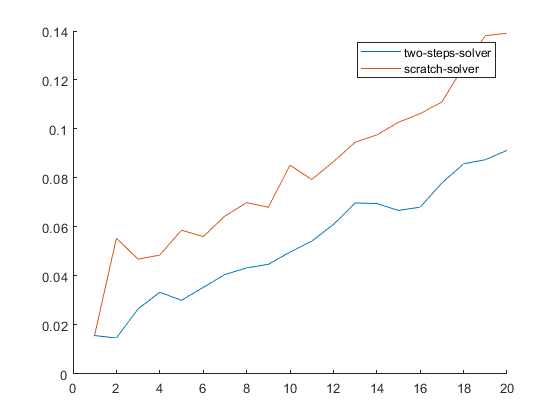

T = importfile('ML-CUP19-TR.csv');
A = T(:, 1:size(T, 2) - 2);
b = T(:, size(T, 2) - 1:end);

k_max = 20;

t1 = zeros(1, k_max);
t2 = zeros(1, k_max);

%two-steps vs from scratch
%comp1 = qr + resumeQr + solve
%comp2 = qr + solve
for k = 1:k_max
    B = augment(A, k);
    t2(k) = timeit(@() comp2(B, b));
end

for k = 1:k_max
    B = augment(A, k);
    
    t1(k) = timeit(@() comp1(A, B, b));
end

% n = 1:k_max;
% delta = t1 - t2;
% file_data = [n;t1;t2;delta];
% fileID = fopen('exp3.txt','w');
% fprintf(fileID,'%6s %12s %12s %12s\n','x','twostepLSP', 'scratchLSP', 'Delta');
% fprintf(fileID,'%6.2d %12.8f %12.8f %12.8f\n',file_data);
% fclose(fileID);

clf
hold all
plot(t1)
plot(t2)
legend('two-steps-solver', 'scratch-solver');

Funzioni composte per misurarne il tempo totale

function comp1(A, B, b)
    [vs, R1] = qr_v(A);
    [vs, R1] = resumeQR(vs, R1, B);
    solve(vs, R1, b);
end

function comp2(B, b)
    [vs, R1] = qr_v(B);
    solve(vs, R1, b);
end